## Initialization

load('JPL_horizon_orbital_elements.mat')

ELEMENTS.Properties.VariableNames{3} = 'Perihelion (AU)';
ELEMENTS.Properties.VariableNames{4} = 'Eccentricity';
ELEMENTS.Properties.VariableNames{5} = 'Inclination (degrees)';
ELEMENTS.Properties.VariableNames{6} = 'Argument of perihelion (J2000-Ecliptic)';
ELEMENTS.Properties.VariableNames{8} = 'Time of perihelion passage';

perihelion = ELEMENTS.(3)(:,:);

eccentricity = ELEMENTS.(4)(:,:);

i = size(perihelion);
a = zeros(i);

for c = 1:i
    a(c) = perihelion(c)/(1 - eccentricity(c));
end

nSPC = sum(a(:) <= 34.2 & a(:) > 0)

nSPC = 943


nLPC = sum(a(:) > 34.2)

nLPC = 2466


nHyperbolic = sum(a(:) < 0)

nHyperbolic = 463

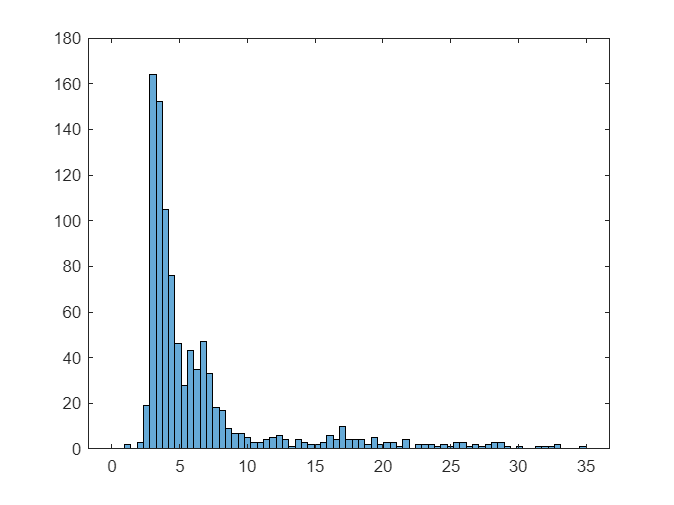


ELEMENTS.Semimaior_axis = a;
ELEMENTS.Properties.VariableNames{10} = 'Semi-major axis (UA)';
ELEMENTS = movevars(ELEMENTS,"Semi-major axis (UA)",'After',"Perihelion (AU)");

%preview semi-maior axis histogram SPC
histogram(ELEMENTS{:,4},75,'BinLimits',[0,35])

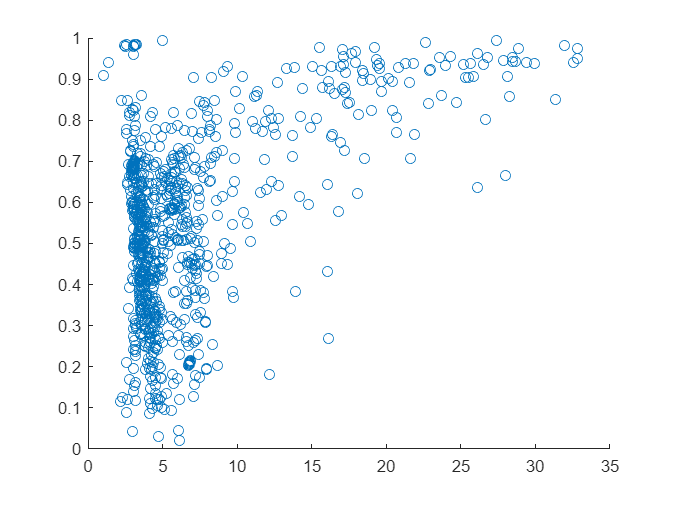


idx = (ELEMENTS{:,4} > 0 ) & (ELEMENTS{:,4} <= 34.2);
SPC = ELEMENTS(idx,:);

%plot semi-maior axis vs eccentricity
scatter(SPC{:,4},SPC{:,5})

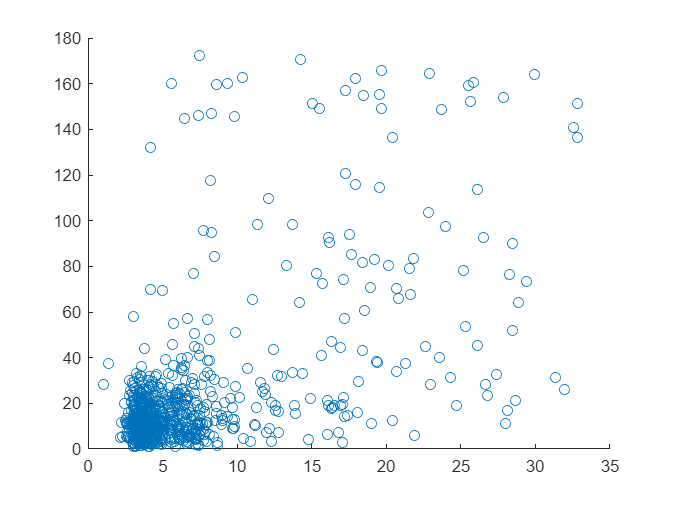

%plot semi-maior axis vs inclination
scatter(SPC{:,4},SPC{:,6})


%reciprocal = (1./perihelion); 
%it can be useful for long period comets
%visualization

## Tisserand

i = nSPC;
Tisserand = zeros(i,1);
%%TisserandA = zeros(i,1);
%%TisserandB = zeros(i,1);
aSPC = SPC.(4)(:,:);
eSPC = SPC.(5)(:,:);
pSPC = SPC.(3)(:,:);
iSPC = SPC.(6)(:,:);
aJ = 5.2038;

for c = 1:i
    %%TisserandA(c) = 5.2038/SPC{c,"Semi-major axis (UA)"} + 2*(((SPC{c,"Perihelion distance (AU)"}/5.2038)*(2-(SPC{c,"Perihelion distance (AU)"}/SPC{c,"Semi-major axis (UA)"})))^1/2) * cosd(SPC{c,"Inclination in degrees, J2000.0 (degrees)"});
    Tisserand(c) = aJ/aSPC(c) + 2*(((1-eSPC(c)^2)*aSPC(c)/aJ)^(1/2))*cosd(iSPC(c));
end

nHTC = sum(Tisserand(:) < 2)

nHTC = 119

nJFC = sum(Tisserand(:) >= 2 & Tisserand(:) <= 3)

nJFC = 739

nMBC = sum(Tisserand(:) > 3)

nMBC = 85

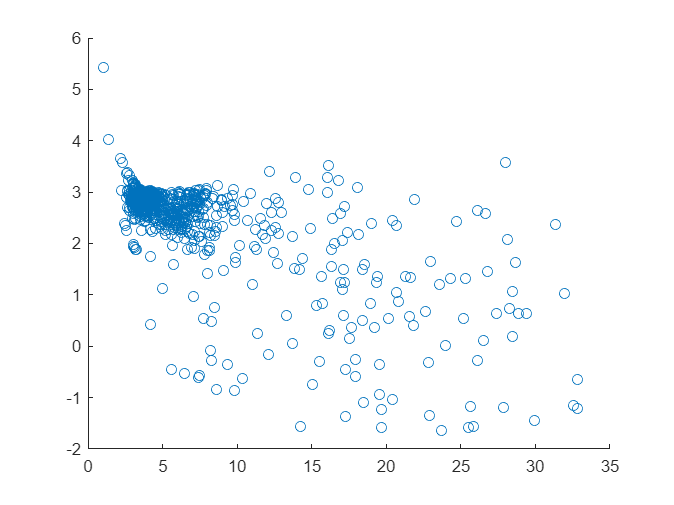


SPC.Tisserand = Tisserand;
SPC = movevars(SPC,"Tisserand",'After',"Inclination (degrees)");
%plot semi-maior axis vs. Tisserand
scatter(SPC{:,4},SPC{:,7})

## Periods

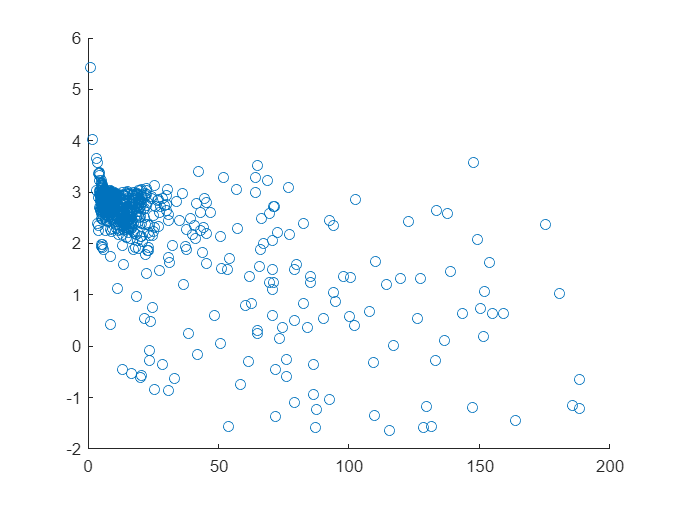

%third Kepler's law at work here, Pc = sqrt(semi-maior axis^3)

Period = zeros(i,1);
for c = 1:i
    Period(c) = aSPC(c)^(3/2);
end

SPC.period = Period;
SPC.Properties.VariableNames{12} = 'Period (years)';
SPC = movevars(SPC,"Period (years)",'After',"Num_Name");
%plot period vs. Tisserand
scatter(SPC{:,2},SPC{:,8})

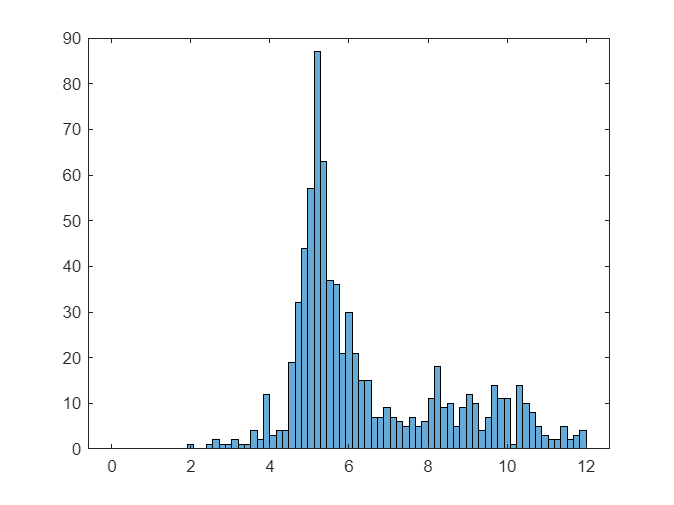

%calculate the aphelion for the SPCs and prints an histogram of it
Aphelion = zeros(i,1);
for c = 1:i
    Aphelion(c) = pSPC(c)*((1+eSPC(c))/(1-eSPC(c)));
end

SPC.period = Aphelion;
SPC.Properties.VariableNames{13} = 'Aphelion (UA)';
SPC = movevars(SPC,"Aphelion (UA)",'After',"Perihelion (AU)");

%histogram of aphelions for SPC //note the peaks around Jupiter and Saturn...
histogram(SPC{:,5},75,'BinLimits',[0,12])


%create tables of JFCs and HTCs from the orbital period, not the Tisserand
%parameter
idx = (SPC{:,2} > 0 ) & (SPC{:,2} <= 20);
JFC = SPC(idx,:);

idx = (SPC{:,2} > 20 ) & (SPC{:,2} <= 200);
HTC = SPC(idx,:);